# Problem 1

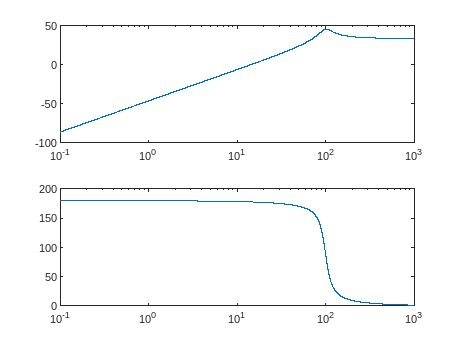

num=[50 0 0];
den=[1 25 10000];
w=logspace(-1,3,10000);

H=freqs(num,den,w);

Hdb=20*log10(abs(H));
HdbPhase=angle(H)*180/pi;
figure(1);
subplot(2,1,1);
semilogx(w,Hdb);
subplot(2,1,2);
semilogx(w,HdbPhase);

## Problem 2

syms r2 r1
[R1,R2]=solve(r2/r1==1000,1/(r1*1e-06)==500)

$$R1 = 2000$$

$$R2 = 2000000$$

## Problem 3

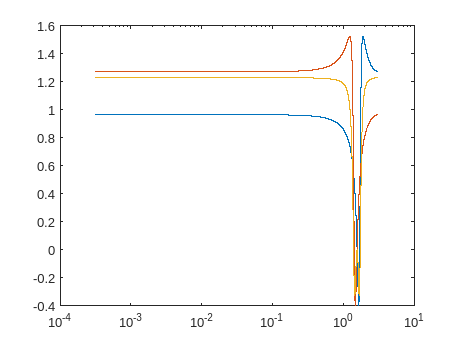

n1=[1 0 1];
n2=[1 0 1];
d1=[1 0.25 0.82];
d2=[1 -0.25 0.82];

[H1,w]=freqz(n1,d1,10000);
H2=freqz(n2,d2,10000);
k=1;
H=k.*H1.*H2;

figure(2);
subplot(1,1,1);
semilogx(w,H1,w,H2,w,H);

## Problem 4

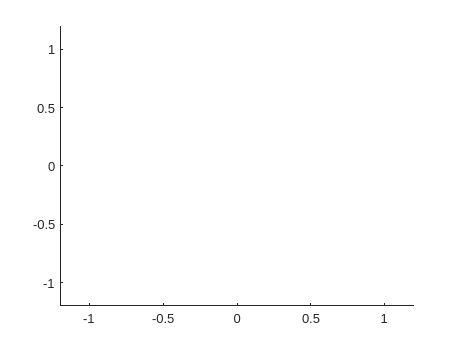

clear all;
figure(3)
n=[6.28e+06];
d=[1 -8];
w=logspace(0,100,10000000);
wnew=2*pi*w;
h=freqs(n,d,wnew);
mag=20*log10(h);
semilogx(w,mag);

## Problem 7

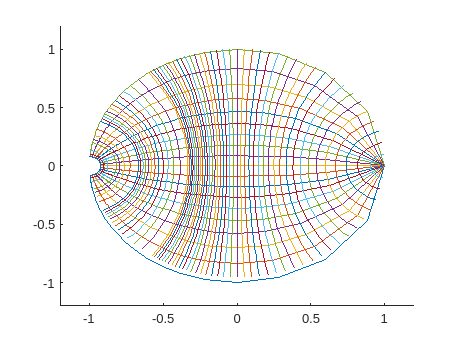

clear all; hold off;clf;clc;
figure(4)
scale=[-1.2,1.2,-1.2,1.2];
axis(scale);

W0Vector=[(0.1:0.1:4.0) (4.5:0.5:10) (12.5:2.5:20) (30:10:50)];

for Angle=-90:10:90
    hold on;
    s=(0:.5:50)*exp(j*(180-Angle)*(pi/180));
    z=Digital.Bilin(s);
    plot(z);
end

for k=1:length(W0Vector)
    s=W0Vector(k)*exp(j*((pi/2):.1:(3*pi)/2));
    z=Digital.Bilin(s);
    plot(z);  
end

## Problem 8

syms r1 r2 r3 r4
solve(20/r1==2,20/r2==1,20/r3==1,(1+(20/((r1*r2*r3)/((1/r1)+(1/r2)+(1/r3)+(1/r4)))))==2)

ans = struct with fields:
    r1: 10
    r2: 20
    r3: 20
    r4: 5/999
